## **Polynomiální regrese:**

Výchozí materiál: Pattern Recognition and Machine Learning (kapitola 1 a kapitola 3).

- Cílem bylo vytvoření modelu pro vytvoření polynomiální regrese  **M**-tého řádu.

- Následně bylo zapotřebí provést aproximace různých řádů polynomu **m **a porovnat jejich výsledky na testovacích datech vůči původní zadané sínusovce.

- Posledním úkolem bylo doplnit model o regularizaci, která pro aproximace vyšších řádů **m** utlumí vyšší koeficienty a tím přiblíži přeučenou aproximaci skutečným datům. Regularizace je jedna z možností jak zpřesnit aproximační model. Dalšá možnost by mohla být např. zvýšení počtu tréninkových dat, ale to samozřejmě může být buď nemožné, nebo drahé.

### Příprava dat:

Testovací funkce je obyčejná sínusovka:

func = @(x) sin(x);                 % testovaná funkce

Vytvoříme N počet vzorků sínusovky z jedné periody a přidáme Gaussovský šum abychom získali trénovací data pro náš regresní model. 

N = 20;                             % počet vzorků
x = 0:((2*pi)/(N-1)):2*pi;          % vzorkovací čas
% t = awgn(func(x),10);             % generátor naměřených dat     

Dále si připravíme testovací data v podobě nezkreslené sínusovky (bez Gaussova šumu).

x_c = 0:((2*pi)/((N*100)-1)):2*pi;  % spojitý čas
t_c = func(x_c);                    % spojitý průběh

**M** odpovídá řádu polynomu, pro který budeme hledat koeficienty aproximačního polynomu.   

M = 3;                              % řád polynomu

### Výpočet a vykreslení aproximace:

První graf vykresluje ideální sínusovku modře a naměřené body zkreslené šumem černě.

figure();
plot(x,t,'kx',x_c,t_c,'b');                     % vykreslení naměřených dat
title("Vypocet a vykresleni lineárni regrese");
xlabel("x (-)");
ylabel("t (-)")
hold on;
warning('off')                                  % zákaz vypisování warning zpráv

Dále do stejného grafu vykreslíme naší spočtenou aproximaci červeně, která je spočtena funkcí **Polynomial_regression. **Ta jako vstupní parametry přijmá trénovací vzorky, řád polynomu a následně regularizaci, která je zde ale nastavena na nulu, aby prozatím neovlivňovala řešení. Místo hodnoty M je zde použit slider pro nastavení libovolného řádu polynomu nula až dvacet.

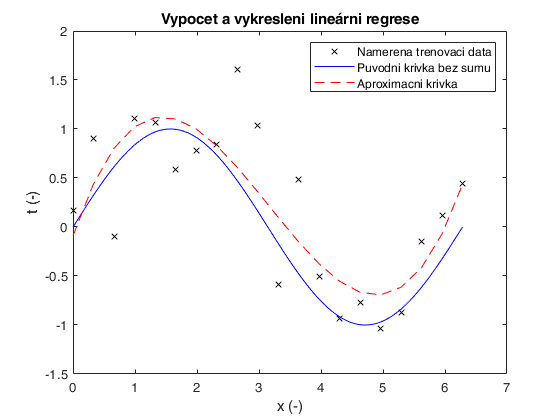

[t_w,~,~,~] = Polynomial_regression(x,t,3,0);   % výpočet aproximace pro M-tý řád polynomu
plot(x,t_w,'r--');                              % vykreslení proložení vypočítaným polynomem M
legend("Namerena trenovaci data","Puvodni krivka bez sumu", "Aproximacni krivka");

### Výpočet aproximace pro několik různých řádů polynomu a jejich porovnání: 

Nyní je cílem vypočítat tuto aproximaci pro hodnoty řádu polynomu nula až **K**.

K = 15;

K tomu si připravíme dva vektory **E_RMS **plné nul. Oba vektory budou obsahovat výpočet chyby aproximace pomocí metody nejmenších čtverců při konkrétním řádu polynomu **M**. Jeden vektor ale bude vyjadřovat chyby tréninkových dat vůči aproximační křivce a druhý bude vyjadřovat chyby aproximační křivky vůči původnímu průběhu (sínusovka). Protože naším cílem není, aby aproximační křivka nutně reprezentovala tetovací data, ale aby co nejvíce odpovídala původní křivce (sínusovce). 

E_RMS = zeros(1,K);
E_RMS_c = zeros(1,K);

V tuhle chvíli je smyčkou spočítána polynomiální regrese pro stejná vstupní data, ale pro různé řády polynomů (nula až **K**). Pro každou iteraci navíc uložíme spočtenou chybu proložení pomocí metody nejmenších čtverců do vektoru **E_RMS**. Následně jsou ve smyčce vypočítány hodnoty aproximační funkce pro testovací data **x_c **a metodou nejmenších čtverů opět zjištěna jejich chyba oproti původní křivce (sínusovce). 

for i = 0:K
    
    [~,w,~,E_w] = Polynomial_regression(x,t,i,0);   % výpočet aproximace
    E_RMS(i+1) = sqrt((2*E_w)/N);                   % výpočet chyby aproximace oproti naměřeným datům

    t_w_c = Polynomial_evaluation(x_c,w);           % aplikace aproximace na testovací data
    e_c = t_c - t_w_c;                              % rozdíly skutečných hodnot funkce oproti aproximaci
    E_RMS_c(i+1) = sqrt((sum(e_c.^2))/(N*100));     % výpočet chyby aproximace oproti původním hodnotám funkce 
end

Nyní je již vykreslen druhý graf, který nese jednak závislost chyby aproximační křivky na hodnotě polynomu (modře). Ale také chybu původní křivky ku aproximační křivce v závislosti na řádu polynomu  (červeně).

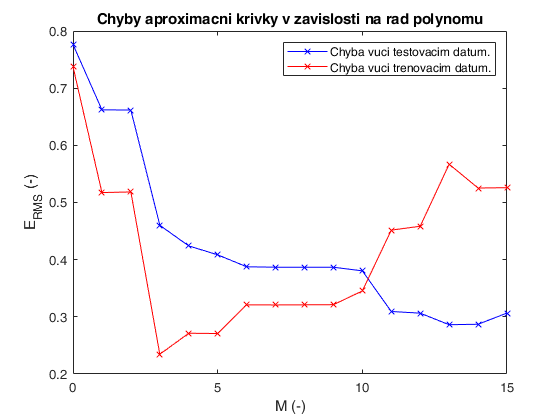

figure();
plot(0:K,E_RMS,'b-x',0:K,E_RMS_c,'r-x');    % vykreslení vývoje chyb aproximace na TRÉNINKOVÝCH a poté na TESTOVACÍCH datech vůči velikosti prokládajícího polynomu
title("Chyby aproximacni krivky v zavislosti na rad polynomu");
xlabel("M (-)");
ylabel("E_{RMS} (-)");
legend("Chyba vuci testovacim datum.","Chyba vuci trenovacim datum.");

### Výpočet a vykreslení aproximace s použitím regularizace:

**M **odpovídá řádu polynomu pro který bude aproximace počítána. Řád polynomu musí být dostatečně velký, aby vypočtená aproximace byla dostatečně přeučená z tréninkových dat byl tak zřetelný vliv regularizace. Regularizace způsobí omezení velkých koeficientů aproximačního polynomu tak, aby aproximace více odpovídala původní křivce.

M = 12;                                                  % řád polynomu

Nyní je vykreslen graf ideální sínusovky modře a naměřených bodů zkreslených šumem černě.

figure();
plot(x,t,'kx',x_c,t_c,'b');                              % vykreslení naměřených dat
hold on;

Následně je spočtena aproximace pro zadanou hodnotu regularizace a výsledná aproximace je zakreslena do stejného grafu.

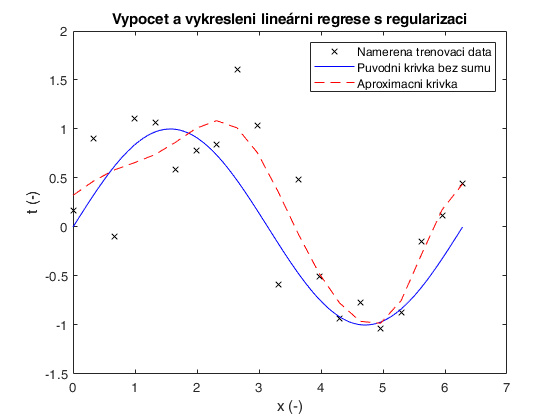

[t_w,w,~,E_w] = Polynomial_regression(x,t,M,10^(-1));   % výpočet aproximace
plot(x,t_w,'r--');
title("Vypocet a vykresleni lineárni regrese s regularizaci");
xlabel("x (-)");
ylabel("t (-)");
legend("Namerena trenovaci data","Puvodni krivka bez sumu", "Aproximacni krivka");

### Výpočet aproximace pro několik různých hodnot regularizace a jejich porovnání:

Příprava hodnot pro regularizaci, která probíhá od hodnoty 10^(**from**) do hodnoty 10^(**to**).   

from = -10;                 
to = 2;
Lambda = (10.^(from:to));   % regularizace v rozmezí nula až jedna, takže můžu zapsat jako inverzní funkci k logaritmu: lambda = 10^(i), kde i je určité záporné číslo (v řádu desítek) max do nuly

Stejně jako u porovnání řádu aproximace, tak i zde si připravíme vektory pro chyb a spočteme  viz výše **"Výpočet aproximace pro několik různých řádů polynomu a jejich porovnání.**

E_RMS = zeros(1,to-from+1);
E_RMS_c = zeros(1,to-from+1);

for i =  1:(to-from+1) 
    [t_w,w,~,E_w] = Polynomial_regression(x,t,M,Lambda(i));   % výpočet aproximace
    E_RMS(i) = sqrt((2*E_w)/N);                         % výpočet chyby aproximace oproti naměřeným datům
  
    t_w_c = Polynomial_evaluation(x_c,w);           % aplikace aproximace na testovací data
    e_c = t_c - t_w_c;                              % rozdíly skutečných hodnot funkce oproti aproximaci
    E_RMS_c(i) = sqrt((sum(e_c.^2))/(N*100));   % výpočet chyby aproximace oproti původním hodnotám funkce 
end

Porovnání aproximací s regularizací vykreslíme do grafu.

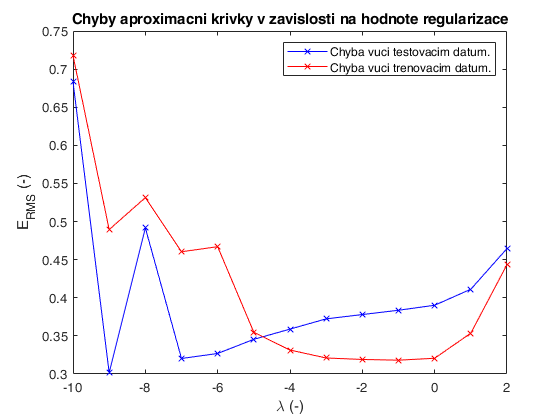

figure();
plot(from:to,E_RMS,'b-x',from:to,E_RMS_c,'r-x');    % vykreslení vývoje chyb aproximace na TRÉNINKOVÝCH a poté na TESTOVACÍCH datech vůči velikosti prokládajícího polynomu
title("Chyby aproximacni krivky v zavislosti na hodnote regularizace");
xlabel("{\lambda} (-)");
ylabel("E_{RMS} (-)");
legend("Chyba vuci testovacim datum.","Chyba vuci trenovacim datum.");